# "Laser scan" line fit example

clear
rosshutdown

Shutting down global node /matlab_global_node_18748 with NodeURI http://10.42.0.28:34365/


init_turtlebot_connection("10.42.0.1", "10.42.0.28");

Initializing global node /matlab_global_node_86385 with NodeURI http://10.42.0.28:39355/


    
% Read scan continously
scansub = rossubscriber('/scan');
velopub = rospublisher('mobile_base/commands/velocity', "Dataformat", "struct");
velomsg = rosmessage(velopub);



while(1)
    
    linescan = receive(scansub); %Receive message
    ranges = linescan.Ranges; % Extract scan
    angles = linescan.AngleMin:linescan.AngleIncrement:linescan.AngleMax;
    
%     plot(angles, ranges)
%     xlabel('Angle [rad]')
%     ylabel('Distance [m]')
    % get data from scan
    cart = readCartesian(linescan);
%     figure()
%     plot(cart(:,2), cart(:,1), '.') % note - y before x..
%     
    
    x = cart(:,2); % x-pos
    d = cart(:,1); % depth
    % only left side
    xleft = x(100:200);
    dleft = d(100:200);
%         plot(xleft, dleft, '.')
%     
    mdl = fitlm(xleft,dleft);
    coef=mdl.Coefficients.Estimate;
    
% 
%         plot(x,d, '.'), hold on
%         plot(x, coef(1) + coef(2)*x, 'r')

    [H,theta,rho] = hough(mat);
    
    % Hough peaks
    Nlines = 5; % Note - Nlines peaks/lines !
    P  = houghpeaks(H,Nlines);
    imshow(H,[],'XData',theta,'YData',rho,'InitialMagnification','fit');
    xlabel('\theta'), ylabel('\rho');
        axis on, axis normal, hold on
    plot(theta(P(:,2)),rho(P(:,1)),'s','color','white');
    lines = houghlines(mat,theta,rho,P,'FillGap',5,'MinLength',7);
    
    imshow(mat), hold on
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    end
    
    lines(3)


    

    x0 = (-coef(1))/coef(2);
    angle = abs(atan(coef(1)/x0))
    distance_weight = 0.1 * (dista - 0.5 )
    angle_weight = 0.5 * ((pi/2)-angle) 
    z = angle_weight + distance_weight

    velomsg.Angular.Z = z;
    velomsg.Linear.X = 0.1;
    
    if angle < 1
        continue
    end
    send(velopub, velomsg);


%      prompt = "Hello";
%      input(prompt, "s");
%     


end


angle = 1.5009

distance_weight = 0.7486

angle_weight = 0.0349

z = 0.7836

angle = -1.4529

distance_weight = -0.1553

angle_weight = 1.5118

z = 1.3566

angle = 0.2832

distance_weight = 0.6376

angle_weight = 0.6438

z = 1.2814

angle = -1.0268

distance_weight = 0.1996

angle_weight = 1.2988

z = 1.4984

angle = -0.8509

distance_weight = 0.1714

angle_weight = 1.2109

z = 1.3822

angle = -1.0762

distance_weight = 0.3053

angle_weight = 1.3235

z = 1.6288

angle = 0.4327

distance_weight = 0.3140

angle_weight = 0.5691

z = 0.8830

angle = 0.5906

distance_weight = 0.7036

angle_weight = 0.4901

z = 1.1937

angle = -1.0994

distance_weight = 0.0843

angle_weight = 1.3351

z = 1.4194

angle = -0.6146

distance_weight = 0.0231

angle_weight = 1.0927

z = 1.1158

angle = -0.1153

distance_weight = 0.0104

angle_weight = 0.8430

z = 0.8534

angle = 0.4200

distance_weight = 0.0105

angle_weight = 0.5754

z = 0.5859

angle = 0.8648

distance_weight = 0.0247

angle_weight = 0.3530

z = 0.3777

angle = 1.1713

distance_weight = 0.0614

angle_weight = 0.1997

z = 0.2612

angle = 1.4280

distance_weight = 0.2266

angle_weight = 0.0714

z = 0.2980

angle = 1.4800

distance_weight = 0.4512

angle_weight = 0.0454

z = 0.4965

angle = -0.4915

distance_weight = 0.5041

angle_weight = 1.0311

z = 1.5352

angle = -0.7244

distance_weight = 0.4094

angle_weight = 1.1476

z = 1.5571

angle = -1.0613

distance_weight = 0.1166

angle_weight = 1.3161

z = 1.4327

angle = -1.0350

distance_weight = 0.3104

angle_weight = 1.3029

z = 1.6133

angle = 0.4696

distance_weight = 0.4876

angle_weight = 0.5506

z = 1.0382

angle = -1.0603

distance_weight = 0.1945

angle_weight = 1.3155

z = 1.5101

angle = -0.6369

distance_weight = 0.0195

angle_weight = 1.1038

z = 1.1233

angle = 0.1462

distance_weight = 0.0048

angle_weight = 0.7123

z = 0.7171

angle = 0.7360

distance_weight = 0.0135

angle_weight = 0.4174

z = 0.4309

angle = 1.1960

distance_weight = 0.0585

angle_weight = 0.1874

z = 0.2459

angle = 1.4272

distance_weight = 0.2034

angle_weight = 0.0718

z = 0.2752

angle = -0.7935

distance_weight = -0.0385

angle_weight = 1.1822

z = 1.1436

angle = -1.1490

distance_weight = 0.3697

angle_weight = 1.3599

z = 1.7296

angle = -0.7900

distance_weight = 0.3648

angle_weight = 1.1804

z = 1.5452

angle = -0.7785

distance_weight = 0.1762

angle_weight = 1.1746

z = 1.3509

angle = -1.0341

distance_weight = 0.3132

angle_weight = 1.3024

z = 1.6156

angle = 0.4856

distance_weight = 0.4889

angle_weight = 0.5426

z = 1.0315

angle = -1.0355

distance_weight = 0.2324

angle_weight = 1.3031

z = 1.5356

angle = -0.6684

distance_weight = 0.0145

angle_weight = 1.1196

z = 1.1341

angle = 0.0709

distance_weight = 1.8257e-04

angle_weight = 0.7500

z = 0.7501

angle = 0.5730

distance_weight = 0.0031

angle_weight = 0.4989

z = 0.5020

angle = 0.9635

distance_weight = 0.0172

angle_weight = 0.3036

z = 0.3209

angle = 1.2695

distance_weight = 0.0623

angle_weight = 0.1507

z = 0.2130

## Multi-line method..

N = 100 % grid size

N = 100


xoffset = min(x)

xoffset = -0.7087

xscale = (max(x)-min(x))

xscale = 3.9949

xi = (x - xoffset)/xscale; % scale to 0-1
xi = round(xi*(N-1))+1; % scale and integer 1 to N
di = (d - min(d))/(max(d)-min(d)); % scale to 0-1
di = round(di*(N-1))+1;
ind = sub2ind([N N], xi, di) % matrix indices

ind =     11
    11
    11
    11
    11
    11
    11
    11
    11
    11


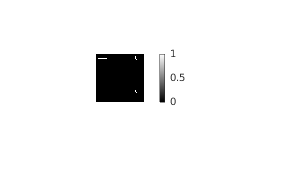


mat = zeros(N); % NxN matrix
mat(ind) = 1; % with points..

imshow(mat), colorbar()

## Hough transform

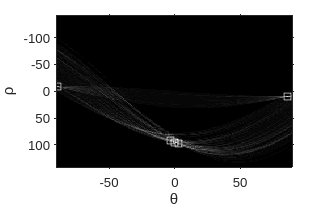

[H,theta,rho] = hough(mat);

% Hough peaks
Nlines = 5; % Note - Nlines peaks/lines !
P  = houghpeaks(H,Nlines);
imshow(H,[],'XData',theta,'YData',rho,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on
plot(theta(P(:,2)),rho(P(:,1)),'s','color','white');

## Hough lines

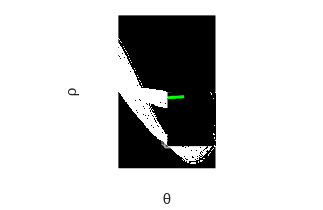

lines = houghlines(mat,theta,rho,P,'FillGap',5,'MinLength',7);

imshow(mat), hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
end


lines(3)

ans = struct with fields:
    point1: [6 10]
    point2: [26 10]
     theta: -89
       rho: -9
